# Physical properties of ice

The physical properties of ice are complicated functions of temperature, grain size and porosity.

We will assume the following characteristic magnitudes for these properties in a convecting ice shell:

phic = 1e-2;  % char. background porosity [1]
dc = 1e-3;    % char. grain size in [m]
Tm = 273;     % melting temperature of ice [K]

Other general physical parameters that will be assumed constant are

muf = 1e-3;   % viscosity of water [Pa s]
R = 8.314;    % gas constant [J/(mol K)]

## Permeability of ice

Permeabiltiy relationship of ice used here comes from van Bargen and Waff (1986) JGR, **91**, B9, 9261-9276 and is given in equation (17) on page 9273 as


$$k = \frac{d^2\phi^2}{1600}$$


for $d=1$mm we get a $k_0 =\frac{d^2 }{1600}=6\ldotp 25\cdot {10}^{-10}$ ${\mathrm{m}}^2$, which is close to the value of $k_0 ={10}^{-9}$ ${\mathrm{m}}^2$ chosen by Kalasouva et al. (2014) based on measured ice permeabilites at high porosities.

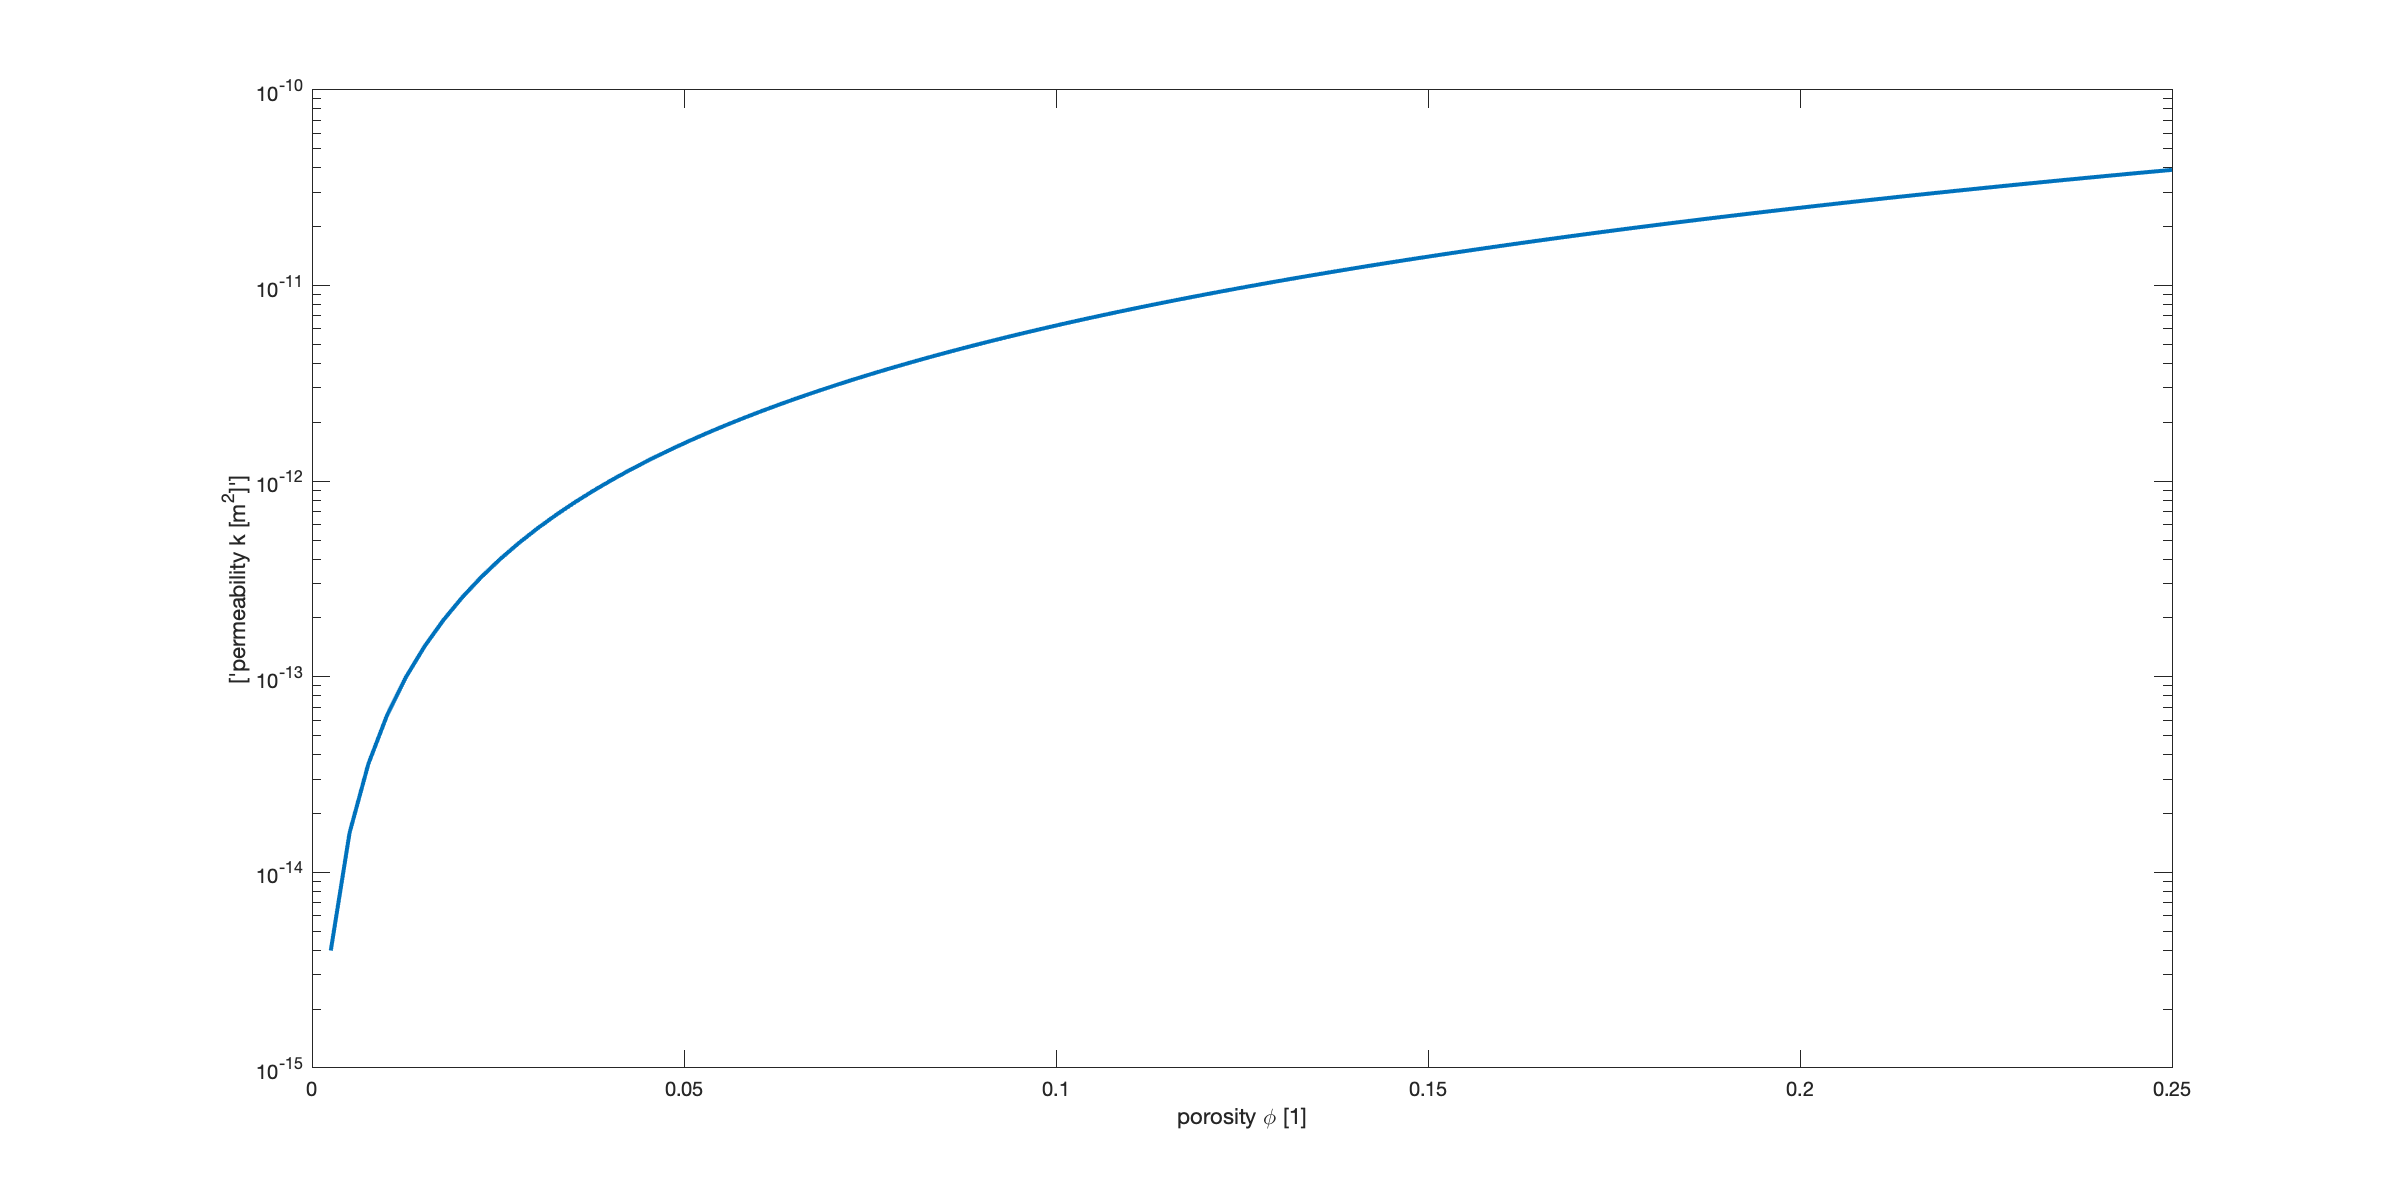

nc = 2;                         % porosity exponent in permeability [1]
tau = 1600;                     % tortuosity [1]
k0 = @(d) d.^2/tau;
k = @(d,phi,n) k0(d).*phi.^n;
kc = k(dc,phic,nc);            
phi = linspace(0,.25,100);

figure('position',[10 10 1200 600])
semilogy(phi,k(dc,phi,nc),'linewidth',2)
xlabel 'porosity \phi [1]'
ylabel ['permeability k [m^2]']

## Shear and bulk viscosity of ice

The temperature dependence of the shear viscosity of pure ice deforming by diffusion creep at low stress is given by Barr and Showman (2009).


$$\eta = \eta_0\exp\left[A\left(\frac{T_m}{T}-1\right)\right]$$


where $T_m$is the melting temperature of the ice and$A$ is the activation energy


$$A=\frac{Q_v^*}{RT}\sim26$$


and the reference viscosity of ice at the melting point, $\eta_0$, ranges from ${10}^{13}$ and ${10}^{15}$ Pa s. 

Vm = 1.97e-5;    % Molar volume of ice I [m^3/mol]
Dov = 9.1e-4;    % volume diffusion constant [m^2/s]
Qvstar = 59.4e3; % volume diffusion activation energy [J/mol]

A = Qvstar/(R*Tm);
eta_diff = @(d,T) (R*T.*d.^2)/(42*Vm*Dov).*exp(Qvstar./(R*T));
eta0 = @(d) eta_diff(d,Tm);
eta = @(d,T,sw,phi) eta0(d).*exp(A*(Tm./T-1)).*exp(-abs(sw)*phi);


The effective bulk viscosity from Hammond et al. (2018)

mc = 1; % porosity exponent in bulk viscosity [1]
xi = @(d,T,sw,phi,m) eta(d,T,sw,phi)./(phi.^m);

## Compaction length of the partially molten ice-shell

delta = @(d,T,sw,phi,m,n) sqrt((xi(d,T,sw,phi,m).*k(d,phi,n))/muf);

## Properties evluated at the char. values

k_c = k(dc,phic,nc)  

k_c = 6.2500e-14

eta_c = eta(dc,Tm,0,phic)

eta_c = 6.9979e+14

xi_c = xi(dc,Tm,0,phic,mc)

xi_c = 6.9979e+16

delta_c = delta(dc,Tm,0,phic,mc,nc)

delta_c = 2.0913e+03

## Temperature dependence of properties

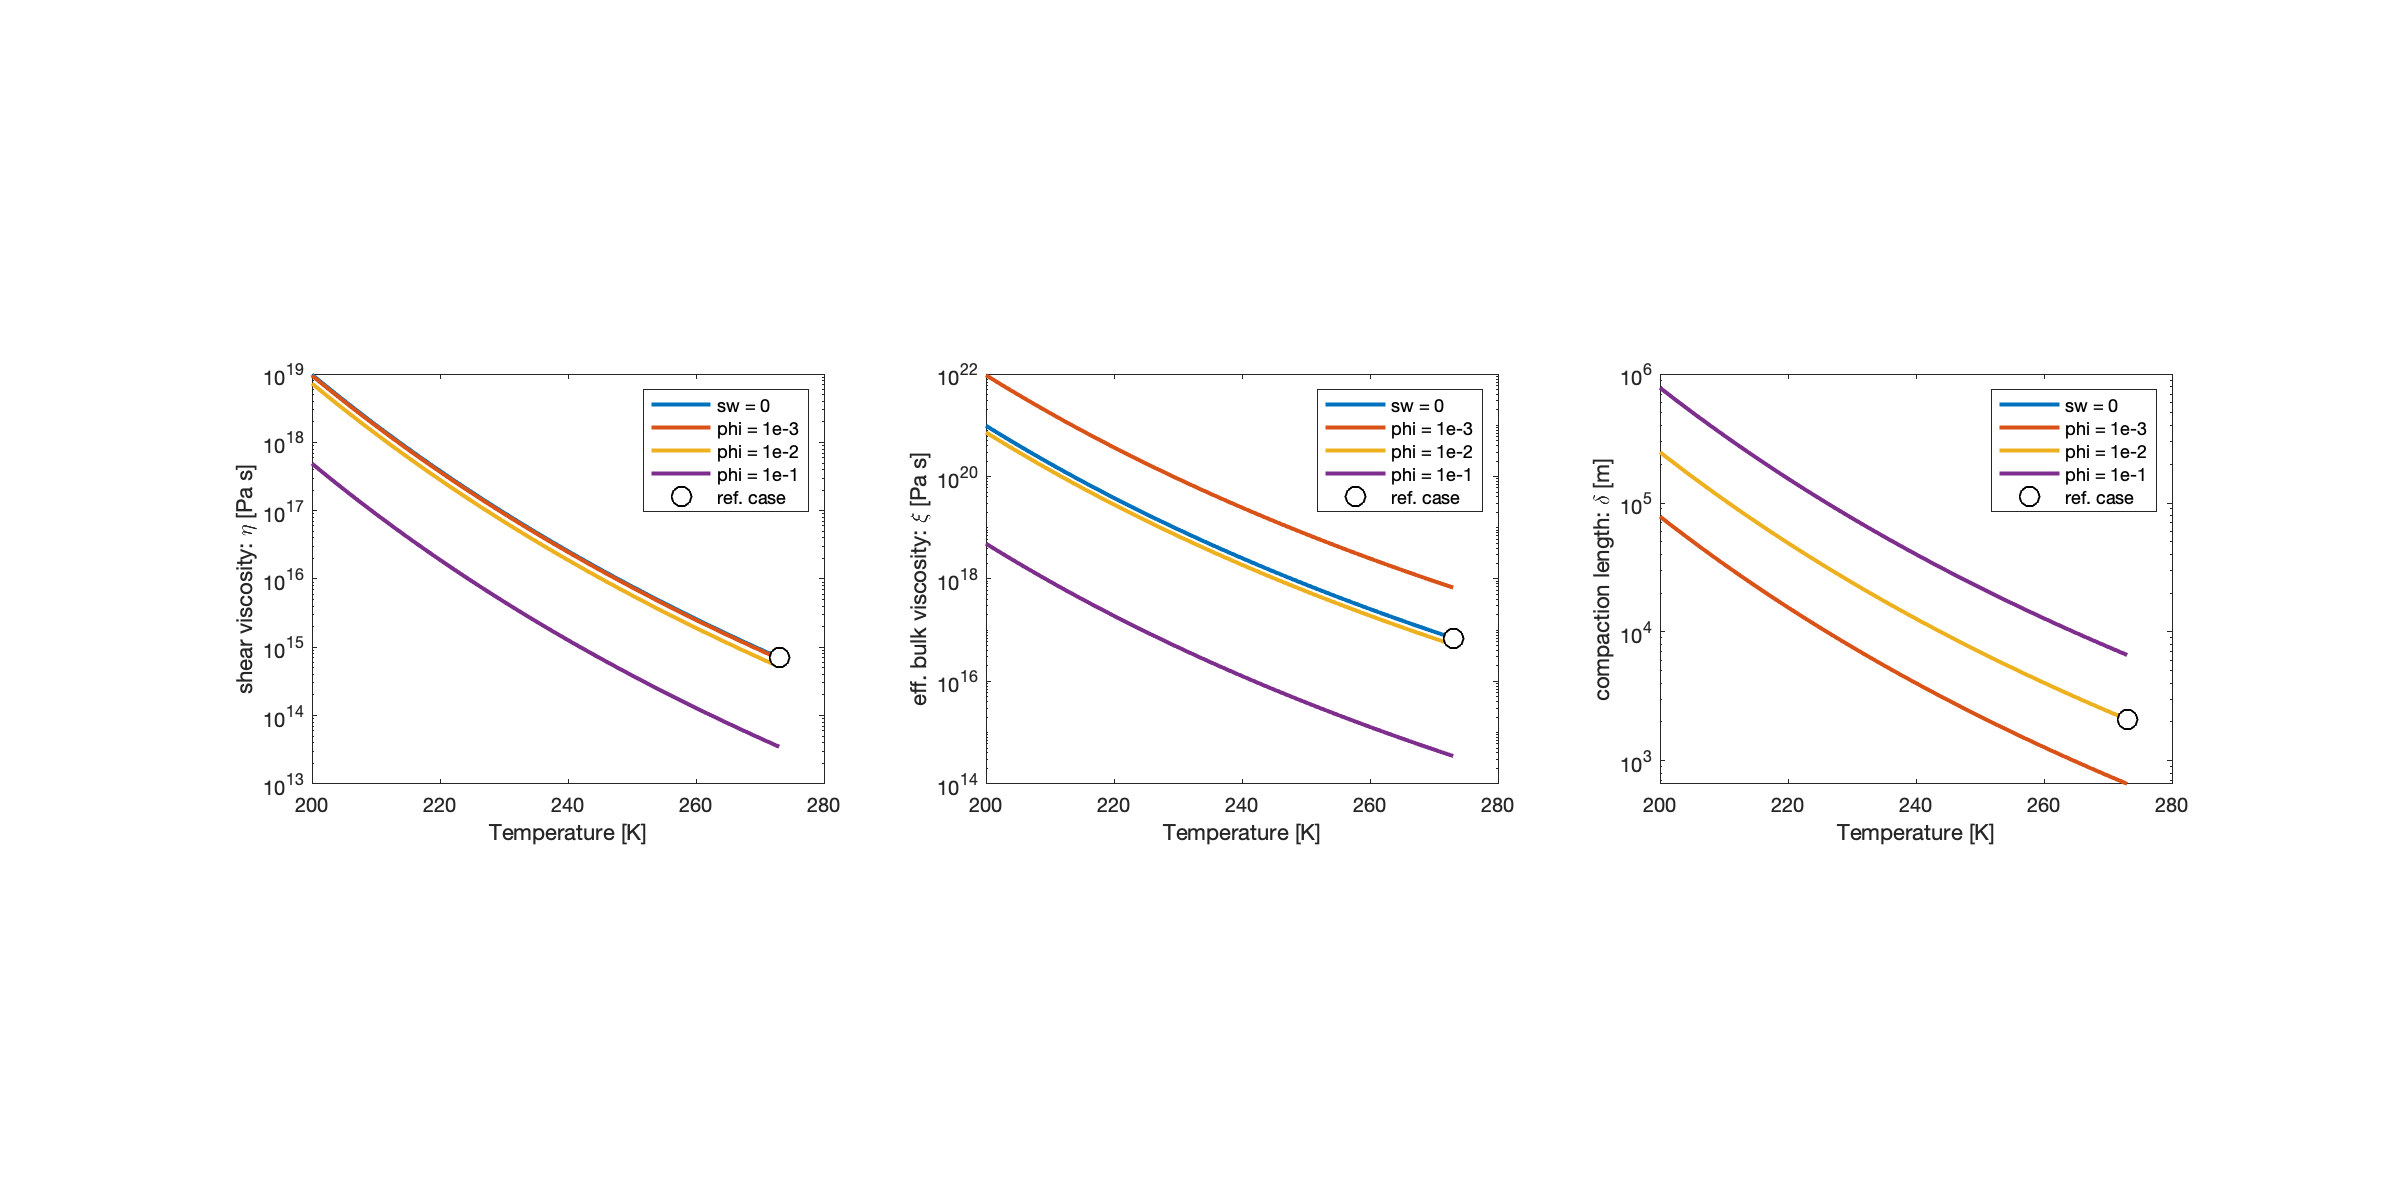

T = linspace(200,273,100);
figure('position',[10 10 1200 600])
clf
subplot 131
semilogy(T,eta(dc,T,0,phic),'linewidth',2), hold on
semilogy(T,eta(dc,T,30,1e-3),'linewidth',2)
semilogy(T,eta(dc,T,30,1e-2),'linewidth',2)
semilogy(T,eta(dc,T,30,1e-1),'linewidth',2)
semilogy(Tm,eta_c,'ko','MarkerFaceColor','w','markersize',10)
pbaspect([1 .8 1])
xlabel 'Temperature [K]'
ylabel 'shear viscosity: \eta [Pa s]'
legend('sw = 0','phi = 1e-3','phi = 1e-2','phi = 1e-1','ref. case')

subplot 132
semilogy(T,xi(dc,T,0,phic,mc),'linewidth',2), hold on
semilogy(T,xi(dc,T,30,1e-3,mc),'linewidth',2)
semilogy(T,xi(dc,T,30,1e-2,mc),'linewidth',2)
semilogy(T,xi(dc,T,30,1e-1,mc),'linewidth',2)
semilogy(Tm,xi_c,'ko','MarkerFaceColor','w','markersize',10)
pbaspect([1 .8 1])
xlabel 'Temperature [K]'
ylabel 'eff. bulk viscosity: \xi [Pa s]'
legend('sw = 0','phi = 1e-3','phi = 1e-2','phi = 1e-1','ref. case')


subplot 133
semilogy(T,delta(dc,T,0,phic,mc,nc),'linewidth',2), hold on
semilogy(T,delta(dc,T,0,1e-3,mc,nc),'linewidth',2)
semilogy(T,delta(dc,T,0,1e-2,mc,nc),'linewidth',2)
semilogy(T,delta(dc,T,0,1e-1,mc,nc),'linewidth',2)
semilogy(Tm,delta_c,'ko','MarkerFaceColor','w','markersize',10)
pbaspect([1 .8 1])
xlabel 'Temperature [K]'
ylabel 'compaction length: \delta [m]'
legend('sw = 0','phi = 1e-3','phi = 1e-2','phi = 1e-1','ref. case')

## Porosity dependence of properties

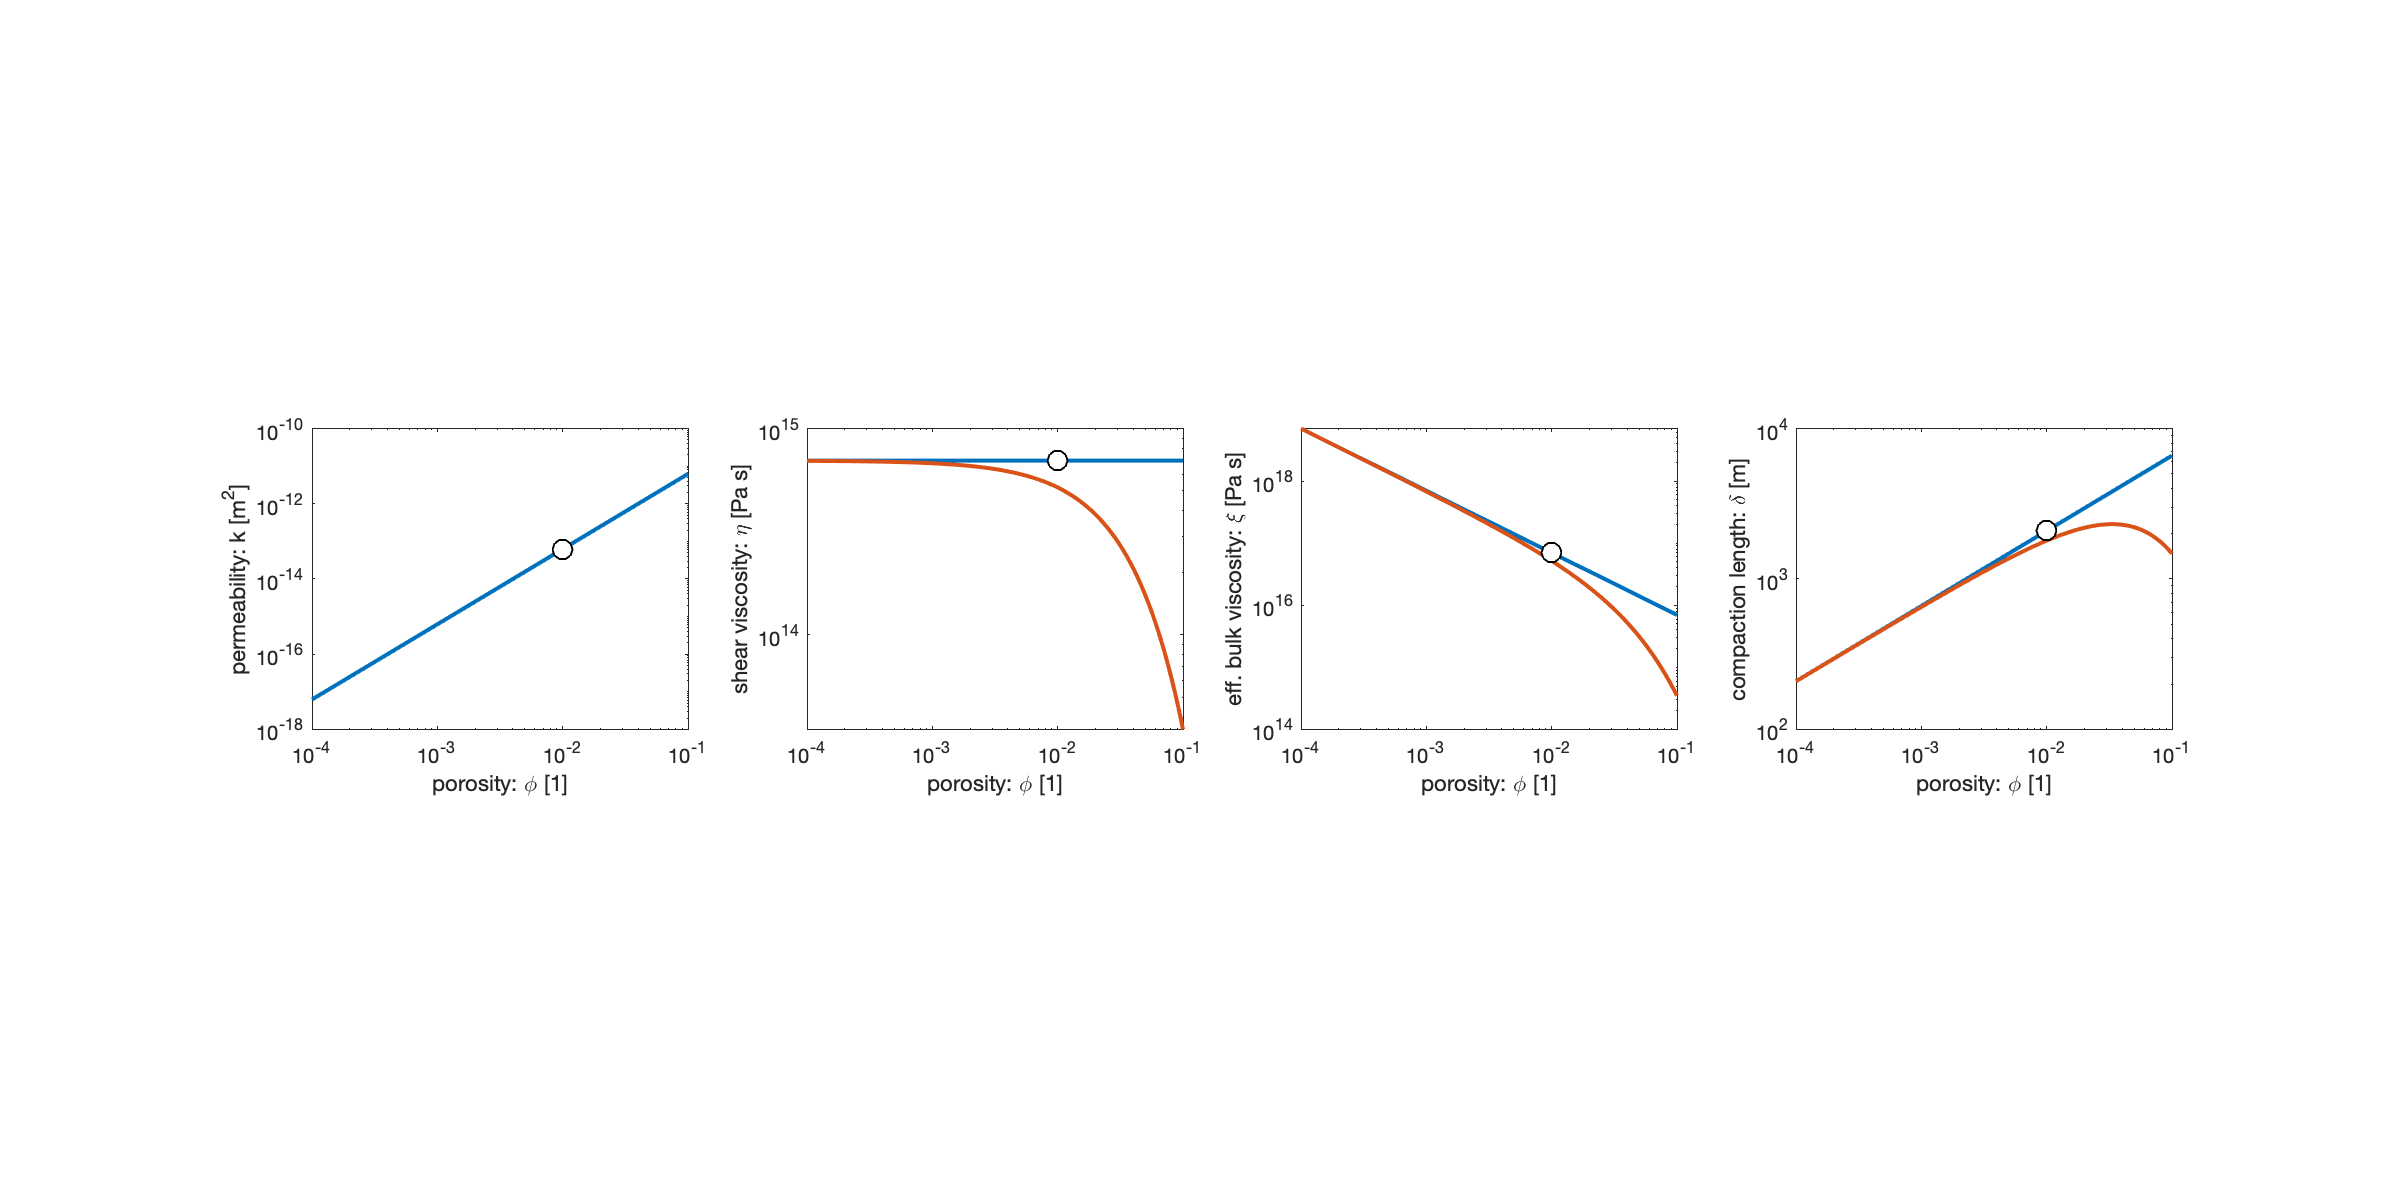

phivec = logspace(-4,-1,1e2);
figure('position',[10 10 1200 600])
subplot 141
loglog(phivec,k(dc,phivec,nc),'linewidth',2), hold on
loglog(phic,k_c,'ko','MarkerFaceColor','w','markersize',10)
pbaspect([1 .8 1])
xlabel 'porosity: \phi [1]'
ylabel 'permeability: k [m^2]'

subplot 142
loglog(phivec,eta(dc,Tm,0,phivec),'linewidth',2), hold on
loglog(phivec,eta(dc,Tm,-30,phivec),'linewidth',2)
loglog(phic,eta_c,'ko','MarkerFaceColor','w','markersize',10)
pbaspect([1 .8 1])
xlabel 'porosity: \phi [1]'
ylabel 'shear viscosity: \eta [Pa s]'

subplot 143
loglog(phivec,xi(dc,Tm,0,phivec,mc),'linewidth',2), hold on
loglog(phivec,xi(dc,Tm,30,phivec,mc),'linewidth',2)
loglog(phic,xi_c,'ko','MarkerFaceColor','w','markersize',10)
pbaspect([1 .8 1])
xlabel 'porosity: \phi [1]'
ylabel 'eff. bulk viscosity: \xi [Pa s]'

subplot 144
loglog(phivec,delta(dc,Tm,0,phivec,mc,nc),'linewidth',2), hold on
loglog(phivec,delta(dc,Tm,30,phivec,mc,nc),'linewidth',2)
loglog(phic,delta_c,'ko','MarkerFaceColor','w','markersize',10)
pbaspect([1 .8 1])
xlabel 'porosity: \phi [1]'
ylabel 'compaction length: \delta [m]'

## Grain size dependence of properties

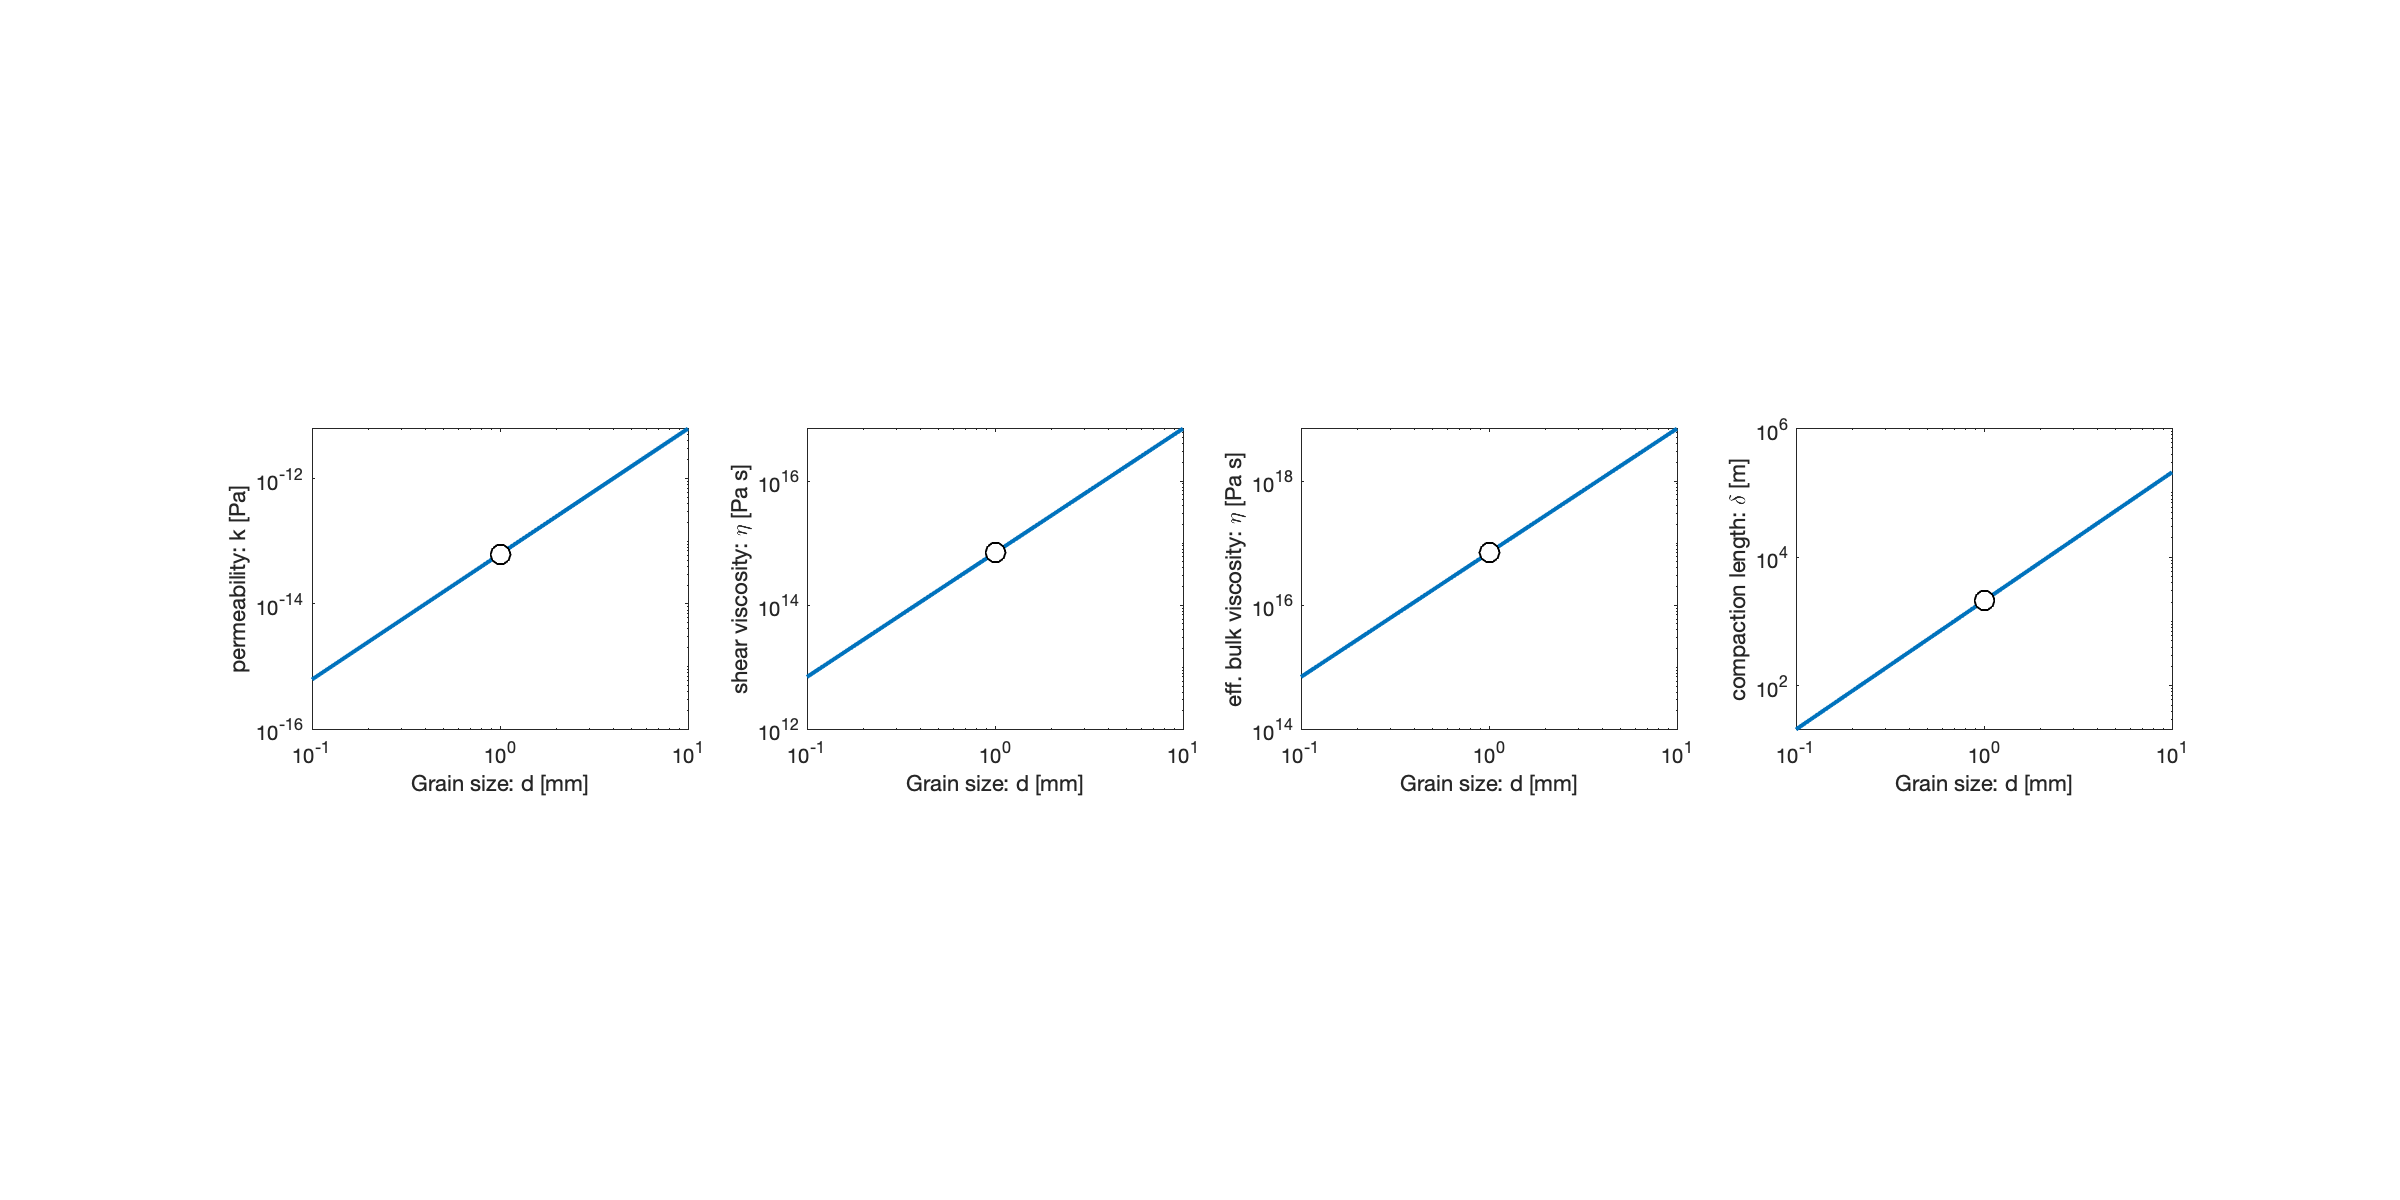

dvec = logspace(-4,-2,1e2);
figure('position',[10 10 1200 600])
subplot 141
loglog(dvec*1e3,k(dvec,phic,nc),'linewidth',2), hold on
loglog(dc*1e3,k_c,'ko','MarkerFaceColor','w','markersize',10)
pbaspect([1 .8 1])
xlabel 'Grain size: d [mm]'
ylabel 'permeability: k [Pa]'

subplot 142
loglog(dvec*1e3,eta(dvec,Tm,0,phic),'linewidth',2), hold on
loglog(dc*1e3,eta_c,'ko','MarkerFaceColor','w','markersize',10)
pbaspect([1 .8 1])
xlabel 'Grain size: d [mm]'
ylabel 'shear viscosity: \eta [Pa s]'

subplot 143
loglog(dvec*1e3,xi(dvec,Tm,0,phic,mc),'linewidth',2), hold on
loglog(dc*1e3,xi_c,'ko','MarkerFaceColor','w','markersize',10)
pbaspect([1 .8 1])
xlabel 'Grain size: d [mm]'
ylabel 'eff. bulk viscosity: \eta [Pa s]'

subplot 144
loglog(dvec*1e3,delta(dvec,Tm,0,phic,mc,nc),'linewidth',2), hold on
loglog(dc*1e3,delta_c,'ko','MarkerFaceColor','w','markersize',10)
pbaspect([1 .8 1])
xlabel 'Grain size: d [mm]'
ylabel 'compaction length: \delta [m]'